% Define the parameters and the system of ODEs
syms u v
f = v^2 + v - u;  % dv/dt
g = 2*v - u;  % du/dt

% Generate a grid of (u, v) values
[v, u] = meshgrid(-1:0.1:5, -1:0.1:5);

% Calculate the derivatives
du = eval(vectorize(f));
dv = eval(vectorize(g));

% Normalize the derivatives for better visualization
du = du ./ sqrt(du.^2 + dv.^2);
dv = dv ./ sqrt(du.^2 + dv.^2);

% Calculate the streamlines
%startx = -1:0.1:5;  % Starting points for the streamlines in the u direction
%starty = repmat(-1, 1, 61);  % Starting points for the streamlines in the v direction
%streamline(v, u, dv, du, startx, starty);
%starty = zeros(1, 61);
%streamline(v, u, dv, du, startx, starty);
%starty = ones(1, 61);
%streamline(v, u, dv, du, startx, starty);
%starty = repmat(2, 1, 61);
%streamline(v, u, dv, du, startx, starty);
%starty = repmat(3, 1, 61);
%streamline(v, u, dv, du, startx, starty);
%starty = repmat(4, 1, 61);
%streamline(v, u, dv, du, startx, starty);
%starty = repmat(5, 1, 61);
%streamline(v, u, dv, du, startx, starty);
startx = -0.5:0.1:2.5;
starty = -1:0.2:5;
streamline(v, u, dv, du, startx, starty);
hold

已锁定最新绘图


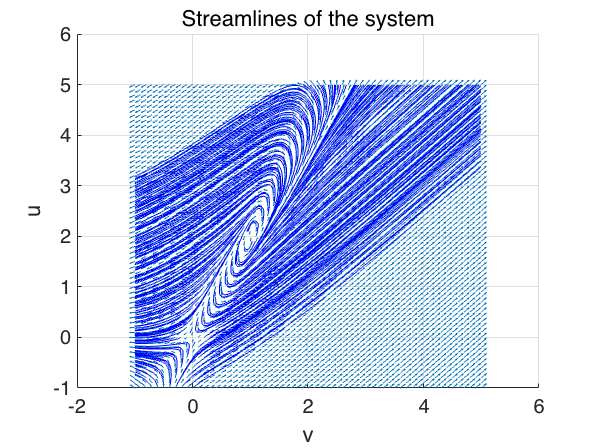

startx = -0.6:0.1:2.4;
streamline(v, u, dv, du, startx, starty);
startx = -0.7:0.1:2.3;
streamline(v, u, dv, du, startx, starty);
startx = -0.8:0.1:2.2;
streamline(v, u, dv, du, startx, starty);
startx = -0.9:0.1:2.1;
streamline(v, u, dv, du, startx, starty);
startx = -1:0.1:2;
streamline(v, u, dv, du, startx, starty);
startx = -0.4:0.1:2.6;
streamline(v, u, dv, du, startx, starty);
startx = -0.3:0.1:2.7;
streamline(v, u, dv, du, startx, starty);
startx = -0.2:0.1:2.8;
streamline(v, u, dv, du, startx, starty);
startx = -0.1:0.1:2.9;
streamline(v, u, dv, du, startx, starty);
startx = 0:0.1:3;
streamline(v, u, dv, du, startx, starty);
quiver(v, u, dv, du);
% Label the plot
xlabel('v');
ylabel('u');
title('Streamlines of the system');
grid on;